%% 한개의 해석지점
copperWinding_sigma=1/1.724E-08  % [S/m]


AC Conductor Loss Split

# AC Loss Calculation

## 1. MotorCAD

[..\..\mlxperPJT\JEETResult_MCADHybridmlx.mlx](matlab:open('..\..\mlxperPJT\JEETResult_MCADHybridmlx.mlx'))

Z:\01_Codes_Projects\git_fork_emach\mlxperPJT\JEETResultCompareScaledLabTable.mlx 

Formula A는 1000rpm에서 맞지만 고속으로 갈수록 오차벌어짐 - popescu

23.2.1은 calcHybridStrandProxImproved1D 이거의 개선버전갖긴함

for mcadNumber=1:1
mcad(mcadNumber)=callMCAD
end
JEETResult_MCADHybridmlx
Z:\01_Codes_Projects\git_fork_emach\mlxperPJT\JEETResultCompareScaledLabTable.mlx


## 2. JMAG AC Loss 

### Transient AC Loss

JMAG=callJmag
app=JMAG
app.GetAppDir
app.Show
Model=app.GetCurrentModel
Model.GetName
NumStudies=Model.NumStudies

JMAGStudyTable=devgetJMAGStudyListTable(Model)
filteredJMAGStudyTable=filterJMAGStudyTableByStudyName(JMAGStudyTable,'Sinusoidal_1')

StepData = defSinglePeriodFromStudyTable(filteredJMAGStudyTable)

EndTime     =StepData.EndTime;
StepDivision=StepData.StepDivision;
xTime=(0:(EndTime/StepDivision):EndTime)';

#### ResultTable 

StudySin=filteredJMAGStudyTable.StudyObj
StudySin.IsValid
StudySin.GetName
LossStudyResultTableObj=StudySin.GetResultTable

% Plot
ResultDataStruct = getJMagResultDatas(LossStudyResultTableObj, 'Joule Loss: W')
AllResultDataStruct = getJMagResultDatas(LossStudyResultTableObj)

AllResultDataStruct.EndTime=EndTime;
AllResultDataStruct.StepDivision=StepDivision;
WireLossTable=filterTablewithString(ResultDataStruct.dataTable,'/Wire');



#### Plot JMAG ResultTable

plotTransientTable(WireLossTable,StepData)
plotJMAGResultDataStruct(AllResultDataStruct,StepData)

#### Multi PurPose Export - Mesh Export (J & Eddy Loss)

WorkDir=JMAG.GetProjectPath


### [TC]Designer Mesh (Element & Node추출)

devgetMeshData함수 사용, 위치는 추출불가능한듯

field 데이터와 element, Node 할당

% StudySin=app.GetCurrentStudy
% StudySin.IsValid
% Model=app.GetModel(0)
% app.View
%  sel=devTempCreateDesignerSelection(app)
% 
%  i_Stator_OD=110
% selectAirByWorldPosSOD(i_Stator_OD,app)
% sel.FaceID


% sel.IsValid
[ElementID, NodeID]=devgetMeshData(app,PartIndex)
devgetMeshData

## [TB]Jquery mesh Mfile

opengmsh
JFT047FeedbackControl
% A = area(msh)
emagE = createpde("electromagnetic")
nodes=1000*msh.POS(:,1:2)';
elements=msh.TRIANGLES(:,1:3)';

centerfig()
hold on
ax=gca

ax.GridAlpha = 0.05
geometryFromMesh(emagE,nodes,elements);
a=pdeplot(emagE.Mesh.Nodes, emagE.Mesh.Elements);

a.Color=[0.90,0.90,0.90]  % grey
area(emagE.Mesh,2)
centerfig()
pdegplot(emagE,"CellLabels","on","FaceAlpha",0.5,FaceLabels="on")



## [TB]JqueryElement

#### [TB]JqueryB Export (JQuery)

### Import B

% 가져오기 옵션을 설정하고 데이터 가져오기
opts = delimitedTextImportOptions("NumVariables", 185);

% 범위 및 구분 기호 지정
opts.DataLines = [3, Inf];
opts.Delimiter = ",";

% 열 이름과 유형 지정
opts.VariableNames = ["ElementID", "Step541_X", "Step542_X", "Step543_X", "Step544_X", "Step545_X", "Step546_X", "Step547_X", "Step548_X", "Step549_X", "Step550_X", "Step551_X", "Step552_X", "Step553_X", "Step554_X", "Step555_X", "Step556_X", "Step557_X", "Step558_X", "Step559_X", "Step560_X", "Step561_X", "Step562_X", "Step563_X", "Step564_X", "Step565_X", "Step566_X", "Step567_X", "Step568_X", "Step569_X", "Step570_X", "Step571_X", "Step572_X", "Step573_X", "Step574_X", "Step575_X", "Step576_X", "Step577_X", "Step578_X", "Step579_X", "Step580_X", "Step581_X", "Step582_X", "Step583_X", "Step584_X", "Step585_X", "Step586_X", "Step587_X", "Step588_X", "Step589_X", "Step590_X", "Step591_X", "Step592_X", "Step593_X", "Step594_X", "Step595_X", "Step596_X", "Step597_X", "Step598_X", "Step599_X", "Step600_X", "Step601_X", "Step602_X", "Step603_X", "Step604_X", "Step605_X", "Step606_X", "Step607_X", "Step608_X", "Step609_X", "Step610_X", "Step611_X", "Step612_X", "Step613_X", "Step614_X", "Step615_X", "Step616_X", "Step617_X", "Step618_X", "Step619_X", "Step620_X", "Step621_X", "Step622_X", "Step623_X", "Step624_X", "Step625_X", "Step626_X", "Step627_X", "Step628_X", "Step629_X", "Step630_X", "Step631_X", "Step632_X", "Step633_X", "Step634_X", "Step635_X", "Step636_X", "Step637_X", "Step638_X", "Step639_X", "Step640_X", "Step641_X", "Step642_X", "Step643_X", "Step644_X", "Step645_X", "Step646_X", "Step647_X", "Step648_X", "Step649_X", "Step650_X", "Step651_X", "Step652_X", "Step653_X", "Step654_X", "Step655_X", "Step656_X", "Step657_X", "Step658_X", "Step659_X", "Step660_X", "Step661_X", "Step662_X", "Step663_X", "Step664_X", "Step665_X", "Step666_X", "Step667_X", "Step668_X", "Step669_X", "Step670_X", "Step671_X", "Step672_X", "Step673_X", "Step674_X", "Step675_X", "Step676_X", "Step677_X", "Step678_X", "Step679_X", "Step680_X", "Step681_X", "Step682_X", "Step683_X", "Step684_X", "Step685_X", "Step686_X", "Step687_X", "Step688_X", "Step689_X", "Step690_X", "Step691_X", "Step692_X", "Step693_X", "Step694_X", "Step695_X", "Step696_X", "Step697_X", "Step698_X", "Step699_X", "Step700_X", "Step701_X", "Step702_X", "Step703_X", "Step704_X", "Step705_X", "Step706_X", "Step707_X", "Step708_X", "Step709_X", "Step710_X", "Step711_X", "Step712_X", "Step713_X", "Step714_X", "Step715_X", "Step716_X", "Step717_X", "Step718_X", "Step719_X", "Step720_X", "Step721_X", "PositionX", "PositionY", "PositionZ"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% 파일 수준 속성 지정
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 데이터 가져오기
Bx2 = readtable("Z:\Thesis\00_Theory_Prof\JFTZIP\JFT047FeedbackControl_backup\Bx.csv", opts);

% 가져오기 옵션을 설정하고 데이터 가져오기
opts2 = delimitedTextImportOptions("NumVariables", 185);

% 범위 및 구분 기호 지정
opts2.DataLines = [3, Inf];
opts2.Delimiter = ",";

% 열 이름과 유형 지정
opts2.VariableNames = ["ElementID", "Step541_X", "Step542_X", "Step543_X", "Step544_X", "Step545_X", "Step546_X", "Step547_X", "Step548_X", "Step549_X", "Step550_X", "Step551_X", "Step552_X", "Step553_X", "Step554_X", "Step555_X", "Step556_X", "Step557_X", "Step558_X", "Step559_X", "Step560_X", "Step561_X", "Step562_X", "Step563_X", "Step564_X", "Step565_X", "Step566_X", "Step567_X", "Step568_X", "Step569_X", "Step570_X", "Step571_X", "Step572_X", "Step573_X", "Step574_X", "Step575_X", "Step576_X", "Step577_X", "Step578_X", "Step579_X", "Step580_X", "Step581_X", "Step582_X", "Step583_X", "Step584_X", "Step585_X", "Step586_X", "Step587_X", "Step588_X", "Step589_X", "Step590_X", "Step591_X", "Step592_X", "Step593_X", "Step594_X", "Step595_X", "Step596_X", "Step597_X", "Step598_X", "Step599_X", "Step600_X", "Step601_X", "Step602_X", "Step603_X", "Step604_X", "Step605_X", "Step606_X", "Step607_X", "Step608_X", "Step609_X", "Step610_X", "Step611_X", "Step612_X", "Step613_X", "Step614_X", "Step615_X", "Step616_X", "Step617_X", "Step618_X", "Step619_X", "Step620_X", "Step621_X", "Step622_X", "Step623_X", "Step624_X", "Step625_X", "Step626_X", "Step627_X", "Step628_X", "Step629_X", "Step630_X", "Step631_X", "Step632_X", "Step633_X", "Step634_X", "Step635_X", "Step636_X", "Step637_X", "Step638_X", "Step639_X", "Step640_X", "Step641_X", "Step642_X", "Step643_X", "Step644_X", "Step645_X", "Step646_X", "Step647_X", "Step648_X", "Step649_X", "Step650_X", "Step651_X", "Step652_X", "Step653_X", "Step654_X", "Step655_X", "Step656_X", "Step657_X", "Step658_X", "Step659_X", "Step660_X", "Step661_X", "Step662_X", "Step663_X", "Step664_X", "Step665_X", "Step666_X", "Step667_X", "Step668_X", "Step669_X", "Step670_X", "Step671_X", "Step672_X", "Step673_X", "Step674_X", "Step675_X", "Step676_X", "Step677_X", "Step678_X", "Step679_X", "Step680_X", "Step681_X", "Step682_X", "Step683_X", "Step684_X", "Step685_X", "Step686_X", "Step687_X", "Step688_X", "Step689_X", "Step690_X", "Step691_X", "Step692_X", "Step693_X", "Step694_X", "Step695_X", "Step696_X", "Step697_X", "Step698_X", "Step699_X", "Step700_X", "Step701_X", "Step702_X", "Step703_X", "Step704_X", "Step705_X", "Step706_X", "Step707_X", "Step708_X", "Step709_X", "Step710_X", "Step711_X", "Step712_X", "Step713_X", "Step714_X", "Step715_X", "Step716_X", "Step717_X", "Step718_X", "Step719_X", "Step720_X", "Step721_X", "PositionX", "PositionY", "PositionZ"];
opts2.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% 파일 수준 속성 지정
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% 데이터 가져오기
By2 = readtable("Z:\Thesis\00_Theory_Prof\JFTZIP\JFT047FeedbackControl_backup\\By.csv", opts2);

% 임시 변수 지우기
clear opts2

% 결과 표시
By2

% 변수(열) 이름에서 'position' 문자열이 포함된 열 찾기
idx = contains(Bx2.Properties.VariableNames, 'position','IgnoreCase',true);

Bx2 = setVarAsRowNames(Bx2, 'ElementID');
Bx2=removevars(Bx2,'ElementID')


By2 = setVarAsRowNames(By2, 'ElementID');
By2=removevars(By2,'ElementID')


% 변수(열) 이름에서 'position' 문자열이 포함된 열 찾기
idx = contains(By2.Properties.VariableNames, 'position','IgnoreCase',true);


% 해당하는 열만으로 구성된 새로운 테이블 생성
positionTable = Bx2(:, idx);
% 해당하는 열만으로 구성된 새로운 테이블 생성
% positionTable = By2(:, idx);
Bx=Bx2(:,~idx)

By=By2(:,~idx)

Babs=sqrt(Bx.^2+By.^2)

figure(2)
hold on
quiver(positionTable.PositionX,positionTable.PositionY,Bx(:,2).Variables,By(:,2).Variables)

idx = contains(Bx.Properties.VariableNames, 'Element','IgnoreCase',true);
BxOnly=Bx(:,~idx)

idx = contains(By.Properties.VariableNames, 'Element','IgnoreCase',true);
ByOnly=By(:,~idx)

stem3(positionTable.PositionX,positionTable.PositionY,Babs(:,2).Variables)


#### Plot B

BxMatrix=BxOnly.Variables;
ByMatrix=ByOnly.Variables;
SlotBxMat=BxMatrix;
SlotByMat=ByMatrix;
size(ByMatrix)
for i=2:1:width(BxMatrix)
    % plot(positionTable.PositionX(i)+BxMatrix(i,:),positionTable.PositionY(i)+ByMatrix(i,:),'k')
    quiver(positionTable.PositionX,positionTable.PositionY,BxMatrix(:,i),ByMatrix(:,i),'k','MaxHeadSize',0.1,'Marker','o')
    hold on
end


## Loci Plot

plotVectorFieldLocus(positionTable, SlotBxMat, SlotByMat)

% 현재 figure와 axes 핸들을 가져옵니다.
fig = gcf; % 현재 figure 핸들
ax = gca; % 현재 axes 핸들

% axes의 속성을 구조체로 저장합니다.
axProperties = get(ax);

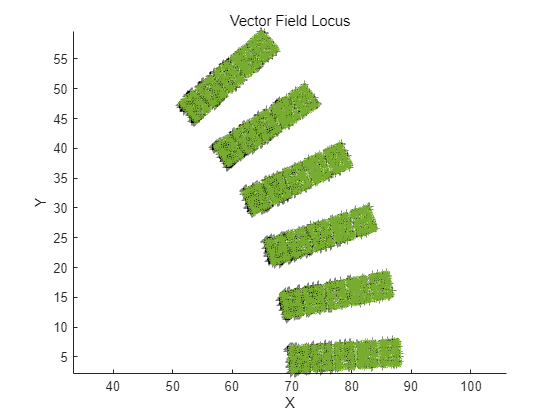


% figure의 내용을 리셋하지만, figure와 axes 설정은 유지합니다.
clf;

% 새로운 axes 객체를 생성하고, 이전 axes의 속성을 적용합니다.
newAx = axes;
set(newAx, axProperties);

% 필요한 경우, 추가적인 설정을 여기에 적용할 수 있습니다.
% 예: set(newAx, 'XGrid', 'on', 'YGrid', 'on');


#### FFT B

BabsTimeinRow=rows2vars(Babs)

BabsTimeinRow = setVarAsRowNames(BabsTimeinRow, 'OriginalVariableNames');
BabsTimeinRow=removevars(BabsTimeinRow,'OriginalVariableNames')
BabsTimeinRow=BabsTimeinRow(2:end,:)


% plot(BabsTimeinRow(:,5000:5100).Variables)

[BabsfftMagTable,BabsfftPhaseTable]=tableFFTwithPhase(BabsTimeinRow)


BxTimeinRow=rows2vars(Bx)
ByTimeinRow=rows2vars(By)

ByTimeinRow = setVarAsRowNames(ByTimeinRow, 'OriginalVariableNames');
ByTimeinRow=removevars(ByTimeinRow,'OriginalVariableNames')

BxTimeinRow = setVarAsRowNames(BxTimeinRow, 'OriginalVariableNames');
BxTimeinRow=removevars(BxTimeinRow,'OriginalVariableNames')
BxTimeinRow=BxTimeinRow(2:end,:)

[BxfftMagTable,BxfftPhaseTable]=tableFFTwithPhase(BxTimeinRow)
[ByfftMagTable,ByfftPhaseTable]=tableFFTwithPhase(ByTimeinRow)

DataUnit='T'

numVariables = width(BxfftMagTable); % 테이블의 변수(열) 수

BxfftMagTable.Properties.VariableUnits = repmat({DataUnit}, 1, numVariables);
numVariables = width(ByfftMagTable); % 테이블의 변수(열) 수
ByfftMagTable.Properties.VariableUnits = repmat({DataUnit}, 1, numVariables);
BabsfftMagTable.Properties.VariableUnits = repmat({DataUnit}, 1, numVariables);

plot1DFFT(BxfftMagTable)


### Import A

% 결과 표시
Az


% 변수(열) 이름에서 'position' 문자열이 포함된 열 찾기
idx = contains(Az.Properties.VariableNames, 'Position','IgnoreCase',true);

% 해당하는 열만으로 구성된 새로운 테이블 생성
NodepositionTable = Az(:, idx);
NodepositionTable.NodeID=Az.NodeID
Az=Az(:,~idx);

NodeID=Az.NodeID;
NodePosX=NodepositionTable.PositionX;
NodePosY=NodepositionTable.PositionY;
NodePosZ=NodepositionTable.PositionZ;
strCellArray = arrayfun(@(x) num2str(x), NodeID, 'UniformOutput', false);

Az.Properties.RowNames=strCellArray
Az.Properties.VariableUnits(1:end)={'Wb/m'}
Az = removevars(Az, ["NodeID"]);


#### B By Part with Element ID

PartStruct=getJMAGDesignerPartStruct(JMAG)

%% WireStruct
idx=findMatchingIndexInStruct(PartStruct,'Name','Wire')
WireStruct=PartStruct(idx)

%% Get Wire Element and Node ID
for Index=1:length(WireStruct)
    WireIndex=WireStruct(Index).partIndex;
    [WireStruct(Index).ElementId, WireStruct(Index).NodeID]=devgetMeshData(app,WireIndex)
end



### Field Data 할당

PostionDatainRow=rows2vars(positionTable)
PostionDatainRow.Properties.RowNames={'xPosition','yPosition','zPosition'}
% %% Ex
% targetValue=8218
% 
% % 일치하는 구조체 인덱스
% matchingIndicesOfStruct=findMatchingIndexInStruct(WireStruct,'ElementId',targetValue)
% 
% % arrayfun을 이용해서 matchingIndicesOfStruct에 해당하는 배열에서 해당 열 찾기
% matchingRows = arrayfun(@(x) find(WireStruct(x).ElementId == targetValue, 1, 'first'), matchingIndicesOfStruct);


WireStruct = updatePartStructWithFieldTable(WireStruct, PostionDatainRow, 'ElementPosition')

WireStruct = updatePartStructWithFieldTable(WireStruct, BabsfftMagTable, 'BabsfftMagTable')
WireStruct = updatePartStructWithFieldTable(WireStruct, BabsTimeinRow, 'BabsTimeinRow')
WireStruct = updatePartStructWithFieldTable(WireStruct, BxfftMagTable, 'BxfftMagTable')
WireStruct = updatePartStructWithFieldTable(WireStruct, ByfftMagTable, 'ByfftMagTable')
WireStruct = updatePartStructWithFieldTable(WireStruct, BxTimeinRow, 'BxTimeinRow')
WireStruct = updatePartStructWithFieldTable(WireStruct, ByTimeinRow, 'ByTimeinRow')


#### Part별 Field Plot

for PartIndex=1:length(WireStruct)
quiverWithFieldTableinPartStruct(WireStruct,PartIndex)
hold on
end

## element 위치로부터 Node 할당?

nodePositions=[NodePosX NodePosY]
elementPositions=[positionTable.PositionX positionTable.PositionY]
elementIndex=positionTable.Properties.RowNames
% elementNodeIndices = findNodesFromElementPositions(nodePositions, elementPositions)
elementNodeIndices = assignNodesToElements(nodePositions, elementPositions, NodepositionTable.NodeID, positionTable.Properties.RowNames)


#### 회전고려해서 Part  분리해줘야됨 ?

addpath(genpath('Z:\01_Codes_Projects\git_SMEKlib'))
HDEVMeshPDEtoolForm=emagE.Mesh;
[HDEVPetFor.p,HDEVPetFor.e,HDEVPetFor.t]=HDEVMeshPDEtoolForm.meshToPet();

%
HDEVPetFor.t(4,:)=[]
msh=HDEVPetFor


for i=1:1:1
    A=Az{:,i};
    % figure(i)
    Babs_t = calculate_B(A, msh);
    drawFluxDensity(msh, A); 
end



## 2/27-28 Hybrid 2

### 도체별로 B로 계산

### element별 B로 

BxfftMagTable3 = WireStruct(1).BxfftMagTable{2,1:202};
bar(BxfftMagTable3)

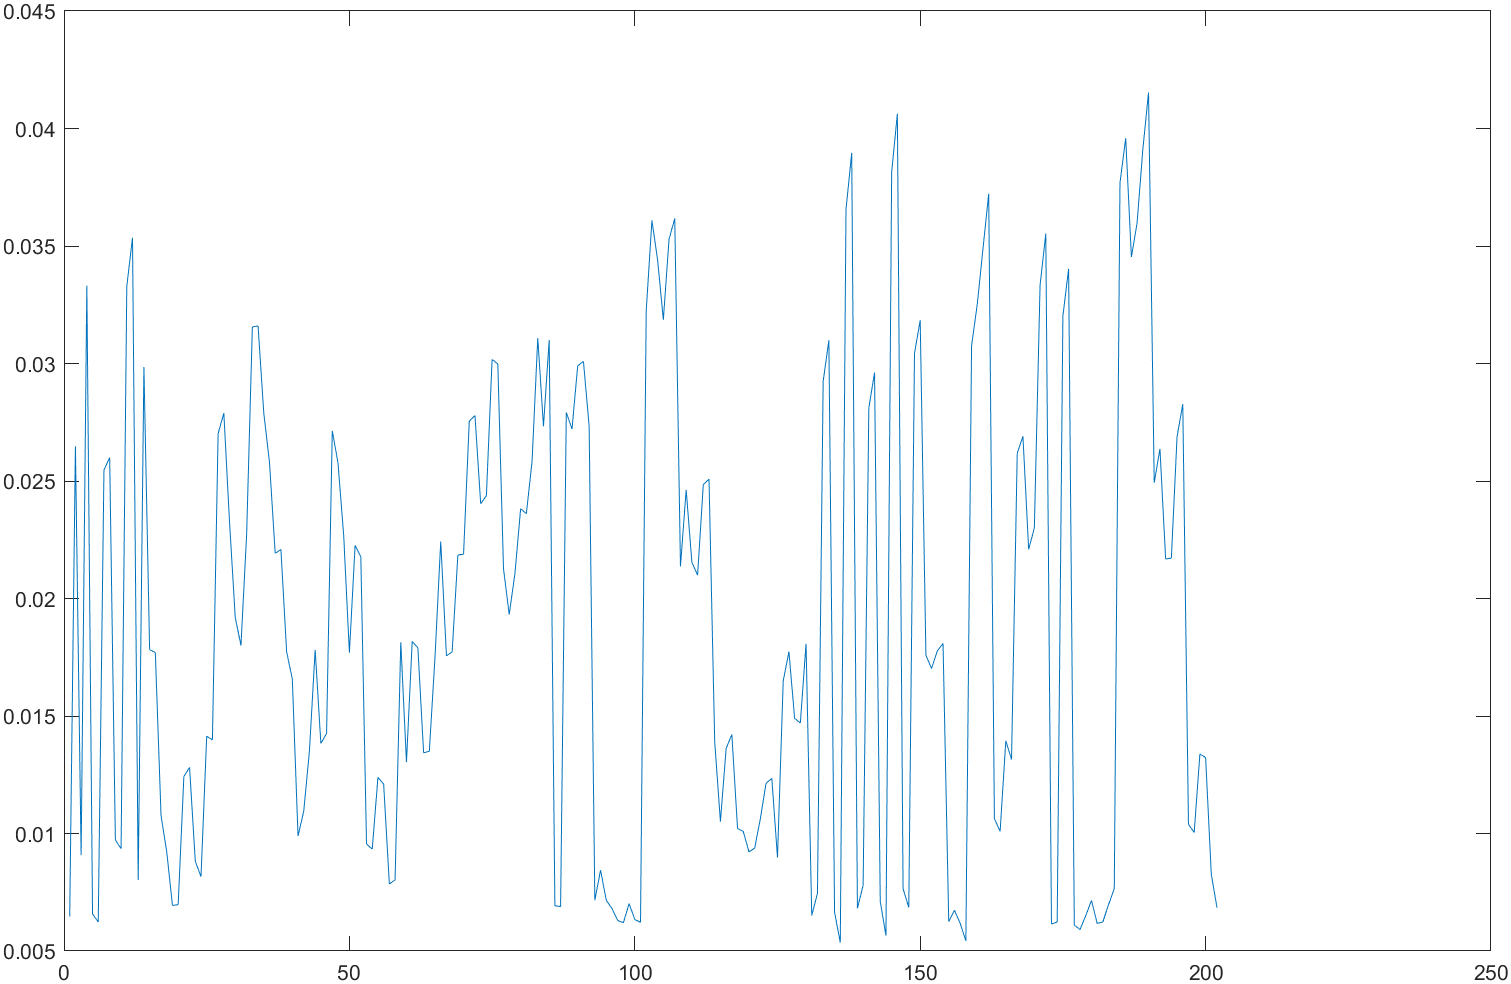

한 도체의 전체 element에 대한 기본파 분포가 이렇게 다양한데 어떤 B를 사용할것인가? 

평균? mean값? 최대값?, 식은 w,h가 없는데 어떤식?

1D Model  - MotorCAD인듯

2D Model - taha 2020 - 근접효과에 대한 두가지 공식과 직교성

## **Hybrid Model **

for AC losses in high speed pmsm for arbitrary flux density [Taha] 2020

 이거를 사용하기 위한 가정은 [Taha] -

Intro : 하이브리드 방법이라고 알려진 FEM과 해석 방법을 결합하면 두 방법의 약점을 극복하고 계산 시간을 줄이면서 정확한 결과를 얻을 수 있습니다.

목적 : 임의 파형과 두 성분을 고려하여 하이브리드 방법을 제시하는 것

- 정현파 전류공급에 대한 skin Effect

- 두 구성요소 (radial/tangential)을 고려한 자속밀도의 임의파형에 대한 근접효과 공식 

- 직교성 (스킨효과와 근접효과를 합산할수 있는 근거)

calcHybridACLossWave.mlx 내부에 설명 상세히 있음

### Skin Effect Model

calcSkinDepth

% SpeedList=[1000:1000:15000];
delta=calcSkinDepth(omega2freq(rpm2OmegaE(SpeedList,4))) % 2.25594 -
% delta>>h 가정에 대부분의 hairpin은 자유로울수 없음

정확하게 범위 

d_limit=0.5*delta;
conductorDia=3
isinDlimit=conductorDia<d_limit

% Generate frequency range for the plot
frequency = linspace(10, 2000); % Adjust range as needed
frequency = linspace(omega2freq(rpm2OmegaE(1000,4)), omega2freq(rpm2OmegaE(20000,4))); % Adjust range as needed

% Calculate skin depth for each frequency
skin_depth = arrayfun(@calcSkinDepth, frequency);

% Plot the results
figure;
plot(frequency, skin_depth*0.5);
xlabel('Frequency (Hz)');
ylabel('Skin Depth (mm)');
title('Skin Depth vs Frequency');
grid on;


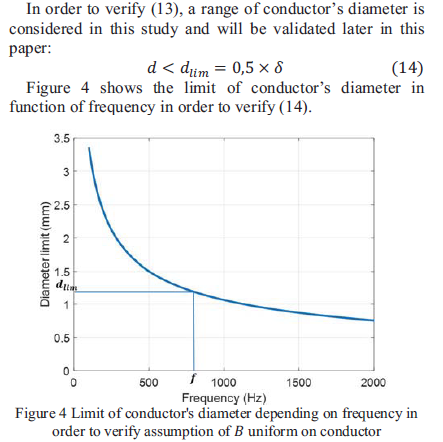

위 함수로부터 구한 delta를 이용해서 gamma를 구하고 이로부터 DC저항으로부터 비율을 산정 -이 비율은 kelvin function을 이용해서 정의

[한계]정현파 전류에 대해서만 적용됨 

[20]에서 각 고조파로 인한 손실을 합산할것을 제안 

[1984 P. S. Venkatraman], "Winding eddy current losses in switch mode power transformers due to rectangular wave currents," in Proc. 

### 2.Proximity Effect Model : 

가정

- 도체에서 플럭스 밀도 $B$가 균일하다,

- 와전류의 글로벌 필드에 대한 기여도는 무시할 수 있다.

- 외부 자기장 $B_{ext}$ 은 FEM으로 평가된 도체의 기여도가 포함된 전역 자기장 $B_{global}$와 동일하다고 가정한다. 

- Flux density $B$ is uniform on conductor,

- Contribution of eddy currents to global field is negligible,

- External magnetic field $B_{ext}$ is assumed to be equal to global magnetic field $B_{global}$, that includes contribution of the conductor, evaluated by FEM.

=>1번과 3번을 연결하면 도체내 B는 전역 $B_{global}$에 의해 도체내에서 동일하다고 다뤄질것이기 때문에-  즉 FEM으로 전역 자기장, 혹은 도채네 B를  어떻게 산정할지

- 도체 중심에서 자속밀도 값을 추출한다고 [2020taha]

### 1D Method 

$$P_{\text {proximity }}=\frac{\pi \sigma l d^4 B_{\text {ext }, m}^2 \omega^2}{128}$$ (정현파 가정)

(임의의 파형가정)

[7] [2001,C. R. Sullivan], "Computationally efficient winding loss calculation with multiple windings, arbitrary waveforms, and two-dimensional or three-dimensional field geometry

#### parseval's identity

[https://en.wikipedia.org/wiki/Parseval%27s_identity](https://en.wikipedia.org/wiki/Parseval%27s_identity)

파스발 항등식에 따라서 퓨리에급수의 

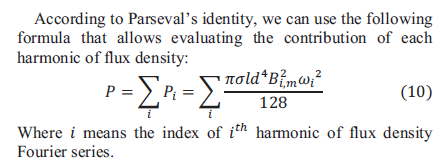

- 도체에서는 성립가능성이, 강판(히스테레시스손실을 포함하는 비선형성이 큰)곳에서보다 성립

### 2D Method

$P_{\text {proximity }}=\frac{1}{T} \int\left(\frac{\pi \sigma l d^4}{64}\left(\frac{d B_r}{d t}\right)^2+\frac{\pi \sigma l d^4}{64}\left(\frac{d B_\theta}{d t}\right)^2\right) d t \\
P_{\text {proximity }}=\sum_{\text {th }}\left(\frac{\pi \sigma l d^4 B_{r, m}^2 \omega_i^2}{128}+\frac{\pi \sigma l d^4 B_{\theta i, m}^2 \omega_i^2}{128}\right)
$ (11,12)

The assumption of flux density $B$ uniform on conductor is equivalent to:

#### 가정 도체경 << 표피효과깊이

[가정]$
$$d \ll \delta$$  (13) [2020taha] 도체(원형도체의)경보다 skin depth가 훨씬 클때 도체내에서 자속밀도가 일정하다는 가정

### 3.Orthogonal Properties [22] 

(element별로 계산해서 더하기) -> J

[TAha] ICEM -> [1990ferreira] 

Total losses are expressed as follows [22]: (역시 B는 Uniform하다는 가정)

$P=\frac{l}{\sigma} \int_{t=0}^T \int\int j^2 \cdot d S \cdot d t=\frac{l}{\sigma} \int_{t=0}^T \int\int\left(j_s+j_p\right)^2 \cdot d S \cdot d t$  (15)

$P=\frac{l}{\sigma} \int_{t=0}^T\left[\int\int\left(j_s+j_p\right)^2 d S+\int_{-\frac{d}{2}}^{\frac{d}{2}} \int_{-\frac{d}{2}}^{\frac{d}{2}} 2 \cdot j_s j_p \cdot d x \cdot d y\right] d t$ (16)

J: element 는 입력밖에 없는데 어떻게 계산?

#### [22] [1990ferreira] 


$$\mathrm{P}_{\mathrm{u}}=\frac{1}{\mathrm{~T} \sigma} \int_{\mathrm{A}} \int_0^{\mathrm{T}}|\mathrm{J}(\mathrm{x}, \mathrm{y})|^2 \mathrm{dt} d \mathrm{~A}$$



$$\mathrm{P}_{\mathrm{u}}=\frac{1}{2 \sigma} \int_{\mathrm{A}}\left(\mathrm{J}_{\mathrm{s}}+\mathrm{J}_{\mathrm{p}}\right)\left(\mathrm{J}_{\mathrm{s}}{ }^*+\mathrm{J}_{\mathrm{p}}{ }^*\right) \mathrm{dA}$$


$\mathrm{P}_{\mathrm{u}}=\frac{1}{2 \sigma} \int_{\mathrm{A}}\left(\mathrm{J}_{\mathrm{s}} \mathrm{J}_{\mathrm{s}}^*+\mathrm{J}_{\mathrm{p}} \mathrm{J}_{\mathrm{p}}^*\right) \mathrm{d} \mathrm{A}$=$=\left(P_{u s}+P_{u p}\right)$


$$\mathrm{P}_{\mathrm{up}}=\mathrm{GH}_{\mathrm{e}}{ }^2$$


$\mathrm{G}=\frac{-2 \pi \gamma}{\sigma} \frac{\text { ber }_2 \gamma \text { ber }^{\prime} \gamma+\text { bei }_2 \gamma \text { ber' }^{\prime} \gamma}{\text { ber }^2 \gamma+\text { bei }^2 \gamma}$ (round)

$$\mathrm{G}=\frac{\frac{\sqrt{\pi}}{2} \mathrm{~d} \xi}{\sigma} \frac{\sinh \xi-\sin \xi}{\cosh \xi+\cos \xi}$$ (rectanguar ) 

아 여기서 나왔구나?

A는 Node

4.고조파를 적게쓸수록 스텝수를 줄일수있음

+5.고조파확인을 통해 후처리로 

### Principle of Similite(원형에서 사각형으로)

## SooHwan


$$$\nabla \times \mathbf{E}_{\mathrm{e}}=-\frac{\partial \mathbf{B}}{\partial t}=-\frac{\partial(\nabla \times \mathbf{A})}{\partial t}$$$



$$\mathbf{J}_{\mathrm{e}}=\sigma \frac{\partial \mathbf{A}}{\partial t}$$


-> $\mathbf{J}_{\mathrm{e}}=\sigma \frac{\partial \mathbf{A}}{\partial t}=\sigma \sum_{i=1}^n N_i(x, y, z) \frac{d \mathbf{A}_i(t)}{d t}
$

#### [WIP] 한 주파수의 A에 대한 전체 요소 J합산 (Node별 A로 요소별 J)

% sigma
J_e = calcElementCurrentDensity(A_dot_e, elements, nodes, copperWinding_sigma);
J_f = calcElementCurrentDensity(A_dot_f, elements, nodes, copperWinding_sigma);




$$$W_{A C, a}(t)=\sum_{i=1}^n \frac{1}{\sigma}\left\{J_{e, i}^2-J_{f, i}^2\right\}(t) \cdot S_i \cdot L$$$


W_AC_a = calcHybridACLossSooHwan(J_e, J_f, S, L, sigma); % 도체별 

이거없이 AC Loss 포함(/미포함에 따른 Scale 효과(x)에 따른 시스템 민감도 비교

## 3. Maxwell

###  LabLink


%% 
% Paccompare=[6.777E-005 0.0003418 0.0008544 0.001612]
% TotalHybAcLoss=sum(Paccompare)
% 
% 
% % ACLossHighFrequencyScaling_Method
% % HybridAdjustmentFactor_ACLosses
% % 
% %%correctionFactor
% correctionFactor=7
% Pac./Paccompare
% (Pac/correctionFactor)./Paccompare
% PacScale=(Pac/correctionFactor)
% %%
% BFlux=[0.02997 0.07131 0.1159 0.1667]
% plot(BFlux)
% meanB=(BFlux/mean(BFlux))
% meanPaccom=(Paccompare/mean(Paccompare))
% meanPac=(Pac/mean(Pac))
% 
% PacScale
% % plot([1 2 3 4],[meanPaccom' meanPac'])
% plot([1 2 3 4],[Paccompare' PacScale'])

% plot([1 2 3 4],[meanB' meanPaccom' meanPac'])
    % Pac2(cIdx)      =   pi*(mm2m(la)*mm2m(Cuboid_Width)*(mm2m(Cuboid_Height))^3*sigma*(omegaE *B     )^2/divCoeffi) ;
    % m^5*[A/mV] * (V*s/m2 )^2  * omega
    % m^4/m^4 * [A/V]*[V^2*s^2] *2pi*f
    % AV*s^2